close all
clear
clc

准备工作

[t,omg,FT,IFT] = prefourier([-20,20],600,[-10*pi,10*pi],600);

定义因果的冲激响应，计算傅里叶变换

alpha = 1;
h = exp(-alpha*t).*(t>=0);
H = FT*h;

用实部的希尔伯特变换得到解析函数（包括实部和虚部，保证逆变换因果）

H1 = conj(hilbert(real(H)));

逆变换到时域验证因果性

h1 = IFT*H1;

绘图

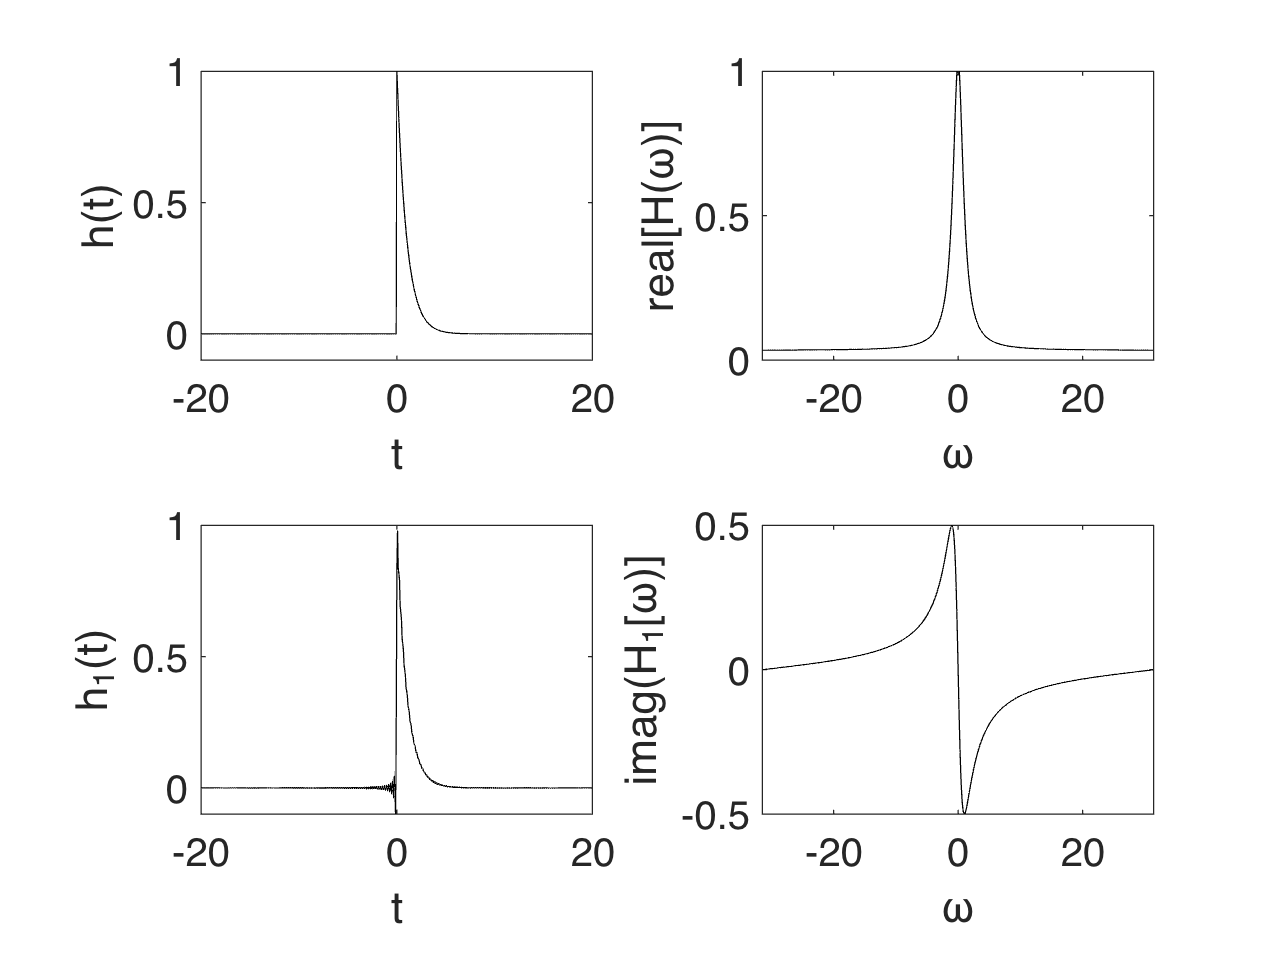

figure, 
subplot(2,2,1), hold on, box on;
plot(t,h,'k-');
set(gca,'FontSize',16,'XLim',[-20 20],'YLim',[-0.1 1]);
xlabel('t');
ylabel('h(t)');
subplot(2,2,2), hold on, box on;
plot(omg,real(H),'k-');
set(gca,'FontSize',16,'XLim',[-10*pi 10*pi],'YLim',[0 1]);
xlabel('\omega');
ylabel('real[H(\omega)]');
subplot(2,2,3), hold on, box on;
plot(t,real(h1),'k-');
set(gca,'FontSize',16,'XLim',[-20 20],'YLim',[-0.1 1]);
xlabel('t');
ylabel('h_1(t)');
subplot(2,2,4), hold on, box on;
plot(omg,imag(H1),'k-');
set(gca,'FontSize',16,'XLim',[-10*pi 10*pi],'YLim',[-0.5 0.5]);
xlabel('\omega');
ylabel('imag(H_1[\omega)]');